% a = arduino

volt0 = 1:100;
volt1 = 1:100;
volt2 = 1:100;


% reading voltage and putting into table
i = 1;
while ( i < 101 )
    voltage0 = readVoltage(a,'A0');
    voltage1 = readVoltage(a,'A1');
    voltage2 = readVoltage(a,'A2');


    volt0(i) = voltage0;
    volt1(i) = voltage1;
    volt2(i) = voltage2;

    i = i + 1;
    pause(.08)
end




% finding average of volts for A0
sum0 = 0;
i0 = 1;
count0 = 0;
while(i0 < 101)
    if volt0(i0) ~= 0
        sum0 = sum0 + volt0(i0);
        count0 = count0 + 1;
    end
    i0 = i0+1;
end
avg0 = sum0 / count0 % AVERAGE OF PRESSURE AT THIS SENSOR

avg0 = 0.9714


% finding average of volts for A1
sum1 = 0;
i1 = 1;
count1 = 0;
while(i1 < 101)
    if volt1(i1) ~= 0
        sum1 = sum1 + volt1(i1);
        count1 = count1 + 1;
    end
    i1 = i1+1;
end
avg1 = sum1 / count1 % AVERAGE OF PRESSURE AT THIS SENSOR

avg1 = 0.0856



% finding average of volts for A2
sum2 = 0;
i2 = 1;
count2 = 0;
while(i2 < 101)
    if volt2(i2) ~= 0
        sum2 = sum2 + volt2(i2);
        count2 = count2 + 1;
    end
    i2 = i2+1;
end
avg2 = sum2 / count2 % AVERAGE OF PRESSURE AT THIS SENSOR

avg2 = 0.0852



% mapping values heatmap
mapValues = [0 0 0 0 0; 
    0 2.5+avg0 2.5+avg1 2.5+avg2 0; 
    0 0 0 0 0 ; 
    0 3 0 0 0; 
    0 0 0 0 0 ; 
    0 0 0 0 0 ; 
    0 0 2.5 2.5 0 ; 
    0 0 0 0 0 ]

mapValues =          0         0         0         0         0
         0    3.4714    2.5856    2.5852         0
         0         0         0         0         0
         0    3.0000         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0    5.0000    5.0000         0
         0         0         0         0         0


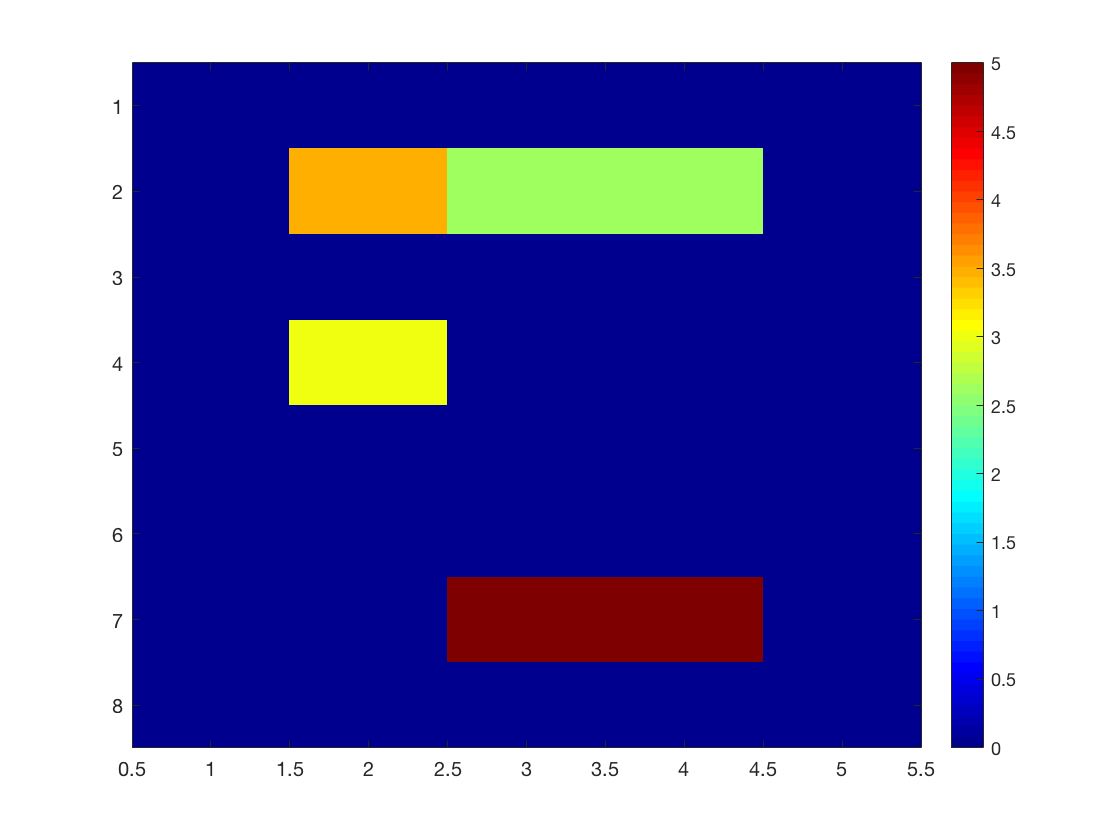

colormap('jet');
imagesc(mapValues);
colorbar